# Vector Part 1:

## Vector and Basic Operation of Vector

### Code Exercise (02_01)

> Three methods for creating vectors.

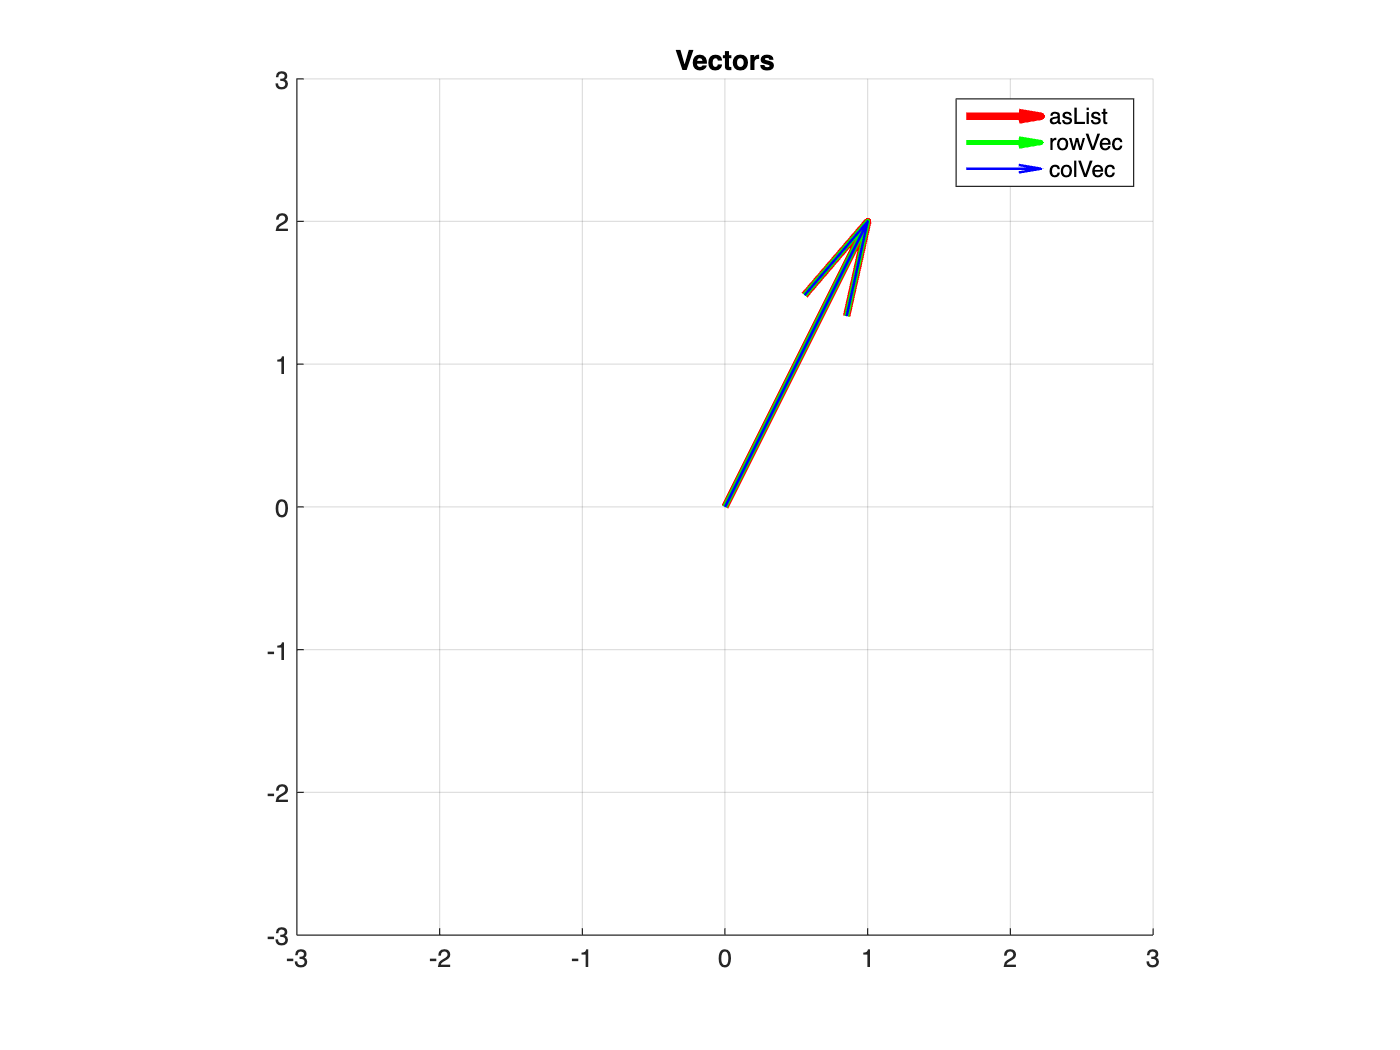

clear; close all; clc;

% Creating a vector as a MATLAB list
asList = [1, 2];

% Creating a row vector
rowVec = [1, 2]; % row

% Creating a column vector
colVec = [1; 2]; % column

% Plotting the vectors using quiver
figure;
hold on;

% To prevent overlap, ther is a 0.1 offset in the starting points of the vectors.
quiver(0, 0, asList(1), asList(2), 'r', 'LineWidth', 3, AutoScale='off', MaxHeadSize=1);
quiver(0, 0, rowVec(1), rowVec(2), 'g', LineWidth=2, AutoScale='off', MaxHeadSize=1);
quiver(0, 0, colVec(1), colVec(2), 'b', LineWidth=1, AutoScale='off', MaxHeadSize=1);

% Set axes properties
axis equal;
xlim([-3, 3]);
ylim([-3, 3]);

% Show grid
grid on;

% Title for the visualization
title('Vectors');

% Legend for vectors
legend('asList', 'rowVec', 'colVec');

### Code Exercise (02_02)

> Generate vectors with different reference points.

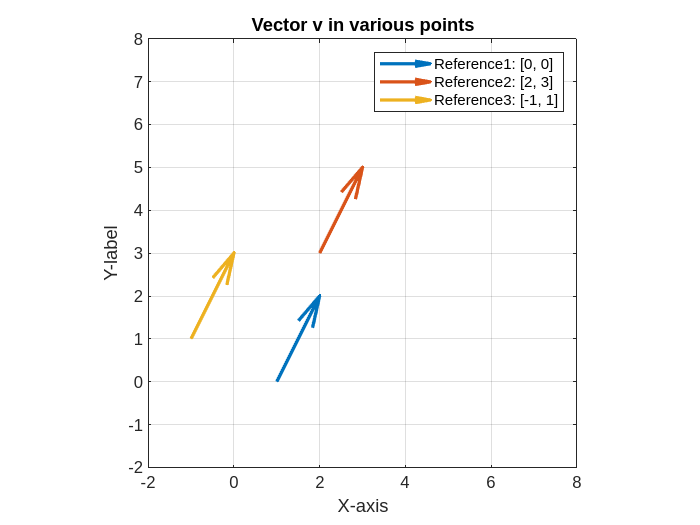

close all; clear; clc;

% Define the vector
v = [1 2];


% Define three different reference points
reference_points = [1, 0; 2, 3; -1, 1];

% Create a figure
figure;

% Plot the vector with each reference point
for i = 1:size(reference_points, 1)
    quiver(reference_points(i, 1), reference_points(i, 2), v(1), v(2), ...
        LineWidth=2, AutoScale="off", MaxHeadSize=2);
    hold on;
end

% Set axes properties
axis equal;
xlim([-2, 8]);
ylim([-2, 8]);

% Show grid
grid on;

% Title for the visualizstion
title('Vector v in various points');

% Axes labels
xlabel('X-axis');
ylabel('Y-label');

% Legend for vectors with different reference points
legend('Reference1: [0, 0]', 'Reference2: [2, 3]', 'Reference3: [-1, 1]');

### Code Exercise (02_03)

> Addition between two vector.

close all; clear; clc;

%% Adding Vectors

% Using 2D vectors here instead of 3D vectors in the book to facilitate
% visualization
v = [1, 2];
w = [4, -6];
vPlusW = v + w;

% print out all three vectors
disp('v:');

v:


disp(v);

     1     2



disp('w:');

w:


disp(w);

     4    -6



disp('vPlusW:');

vPlusW:


disp(vPlusW);

     5    -4



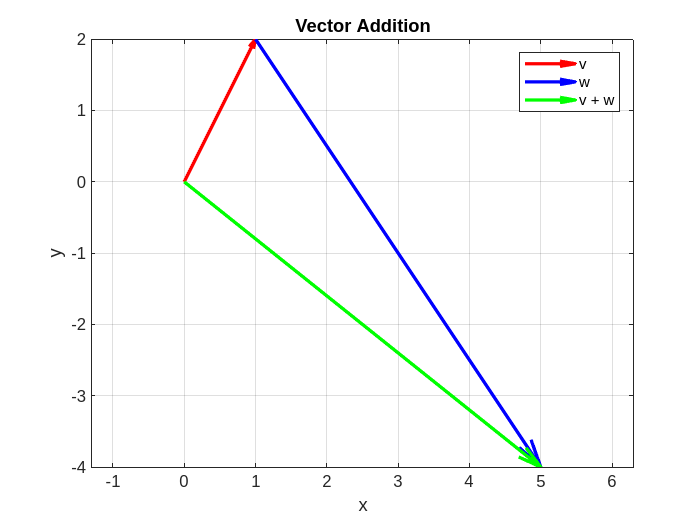


% Plot vectors
quiver(0, 0, v(1), v(2), 0, 'r', LineWidth=2);
hold on;
quiver(v(1), v(2), w(1), w(2), 0, 'b', LineWidth=2);
quiver(0, 0, vPlusW(1), vPlusW(2), 0, 'g', LineWidth=2);
hold off;

axis equal;
xlabel('x');
ylabel('y');
title('Vector Addition');
legend('v', 'w', 'v + w');
grid on;

### Code Exercise (02_04)

> Broadcasting - see diagonal element.

close all; clear; clc;

% column vector and row vector
column_vector = [1; 2; 3];
row_vector = [4 5 6];

% Using 2D vectors here instead of 3D vectors in the book to facilitate
% visualization
sum_result = column_vector + row_vector;
differece_result = column_vector - row_vector;

% print out all three vectors
disp('addition:');

addition:


disp(sum_result);

     5     6     7
     6     7     8
     7     8     9



disp('subtraction:');

subtraction:


disp(differece_result);

    -3    -4    -5
    -2    -3    -4
    -1    -2    -3



### Code Exercise (02_05)

> multiplication between scalar-vector.

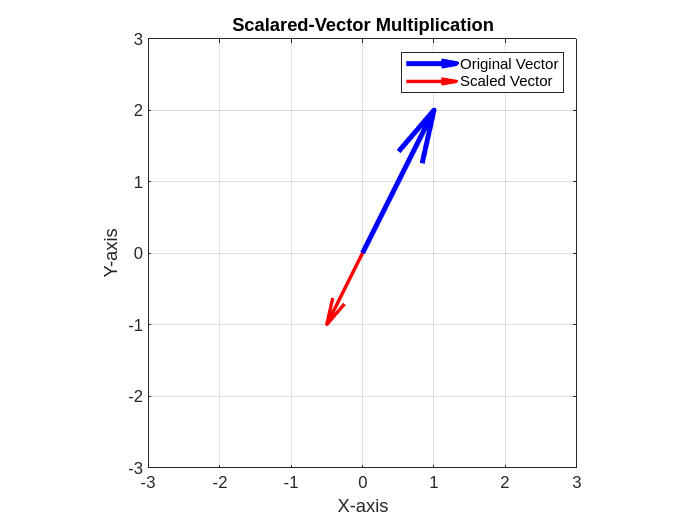

clear; close all; clc;

% Define the vector
v = [1, 2];

% Define the scalar
s = -1/2;

% Compute the scaled vector
scaled_v = s * v;

% Create a figure
figure;

% Plot the original vector
quiver(0, 0, v(1), v(2),'b', LineWidth=3, AutoScale='off', MaxHeadSize=2, DisplayName='Original Vector');
hold on;

% Plot the scaled vector
quiver(0, 0, scaled_v(1), scaled_v(2), 'r', LineWidth=2, AutoScale='off', MaxHeadSize=2, DisplayName='Scaled Vector');

% Set axes properties
axis equal
xlim([-3, 3]);
ylim([-3, 3]);

% Show grid
grid on;

% Title for the visualization
title('Scalared-Vector Multiplication');

% Axes labels
xlabel('X-axis');
ylabel('Y-axis');

% Legend for vectors
% legend('Original Vector', 'Scaled Vector');
legend("show");

### Vector addition

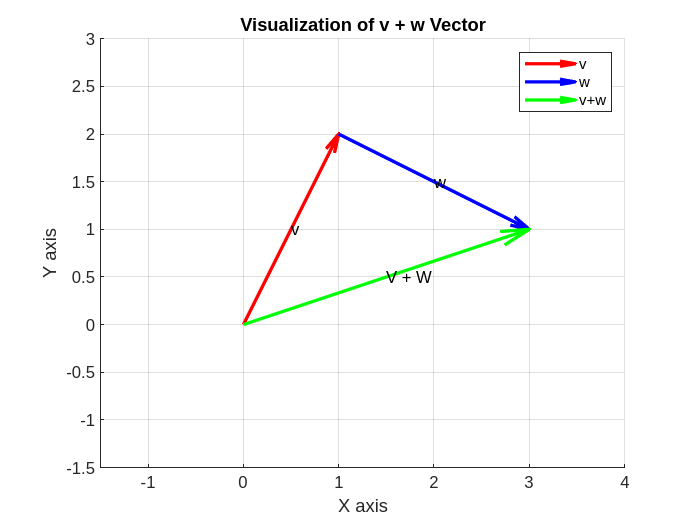

clc; clear; close all;

v = [1 2];
w = [2 -1];
vPlusW = v + w;
vMinusW = v - w;

figure;
hold on;

quiver(0, 0, v(1), v(2), 0, 'r', LineWidth=2, MaxHeadSize=0.3, DisplayName='v');
quiver(v(1), v(2), w(1), w(2),0, 'b', LineWidth=2, MaxHeadSize=0.3, DisplayName='w');
quiver(0, 0, vPlusW(1), vPlusW(2),0, 'g', LineWidth=2, MaxHeadSize=0.3, DisplayName='v+w');

grid on;
axis equal;
xlabel('X axis');
ylabel('Y axis');

title('Visualization of v + w Vector');
%legend('v', 'w', 'v + w');
legend("show");
xlim([-1.5 4]);
ylim([-1.5, 3]);

text(v(1)/2, v(2)/2, 'v');
text(v(1) + w(1)/2, v(2) + w(2)/2, 'w');
text(vPlusW(1)/2, vPlusW(2)/2, 'V + W');
hold off;

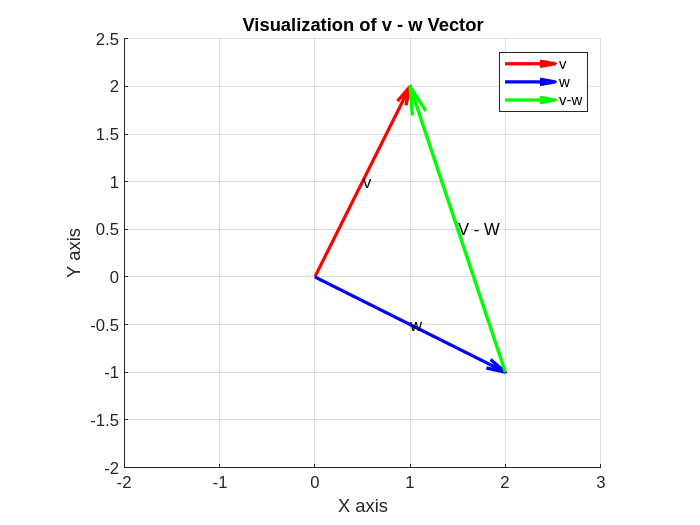


figure;
hold on;

quiver(0, 0, v(1), v(2), 0, 'r', LineWidth=2, MaxHeadSize=0.3, DisplayName='v');
quiver(0, 0, w(1), w(2),0, 'b', LineWidth=2, MaxHeadSize=0.3, DisplayName='w');
quiver(w(1), w(2), vMinusW(1), vMinusW(2),0, 'g', LineWidth=2, MaxHeadSize=0.3, DisplayName='v-w');

title('Visualization of v - w Vector');
axis equal;
grid on;
xlim([-2, 3]);
ylim([-2, 2.5]);

xlabel('X axis');
ylabel('Y axis');

legend("show");


text(v(1)/2, v(2)/2, 'v');
text(w(1)/2, w(2)/2, 'w');
text(w(1) + vMinusW(1)/2, w(2) + vMinusW(2)/2, 'V - W');

hold off

### Code Exercise (02_05)

> multiplication between scalar-vector

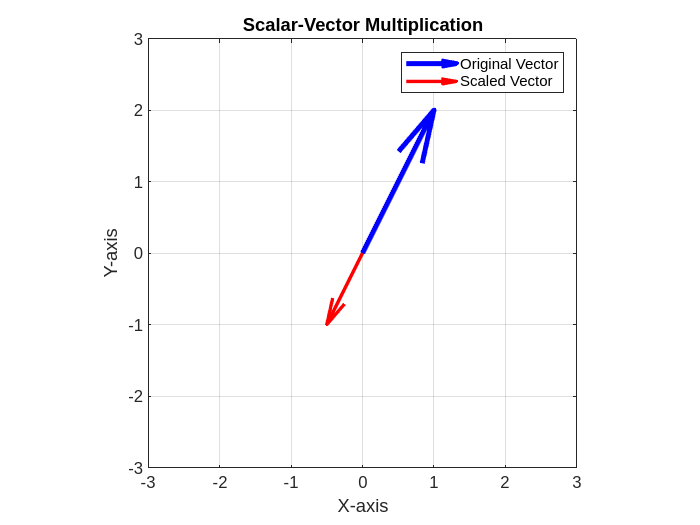

clc; clear; close all;

% Define the vector
v = [1, 2];

% Define the scalar
s = -1/2;

% Compute the scaled vector
scaled_v = s * v;

% Created a figure
figure;

% Plot the original vector
quiver(0, 0, v(1), v(2), 'b', LineWidth=3, AutoScale='off', MaxHeadSize=2, DisplayName='Original Vector');
hold on;

% Plot the scaled vector
quiver(0, 0, scaled_v(1), scaled_v(2), 'r', LineWidth=2, AutoScale='off', MaxHeadSize=2, DisplayName='Scaled Vector');

% Set axes properties
axis equal;
xlim([-3, 3]);
ylim([-3, 3]);

% Show grid
grid on;

% Title for the visualization
title('Scalar-Vector Multiplication');

% Axes labels
xlabel('X-axis');
ylabel('Y-axis');

% Legend for vectors
%legend('Original Vector', 'Scaled Vector')
legend("show");

### Norm

clc; clear; close all;

u = rand(4, 1);
v = rand(4, 1);
uPlusV = u + v;

n1 = norm(u, 2);
n2 = norm(v, 2);
disp(n1 + n2);

    2.3279




disp(norm(uPlusV, 2));

    2.1772



### Code Exercise (02_06)

> Scalar - vector addition.

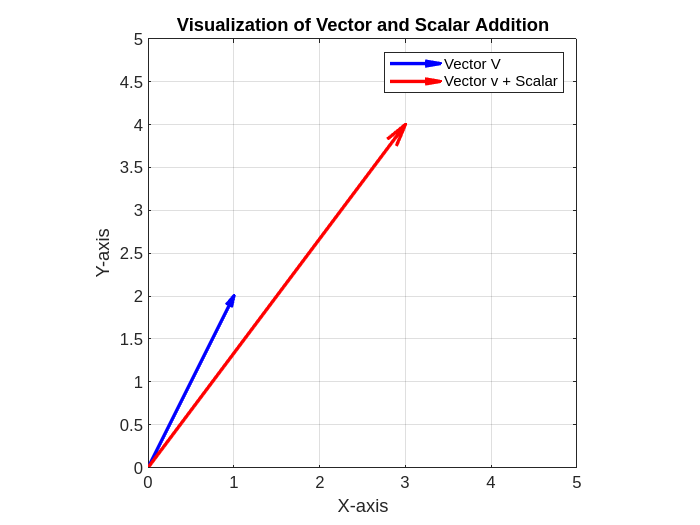

% Define vector
v = [1, 2];

% Define scalar
s = 2;

% Add scalar to vector
v_plus_s = v + s;

% Create figure
figure;

% Display vector v from the origin
quiver(0, 0, v(1), v(2), 'b',LineWidth=2, AutoScale='off', DisplayName='Vector V');
hold on;

% Display vector v + scalar from the origin
quiver(0, 0, v_plus_s(1), v_plus_s(2), 'r', LineWidth=2, AutoScale='off', DisplayName='Vector v + Scalar');

% Set axes
axis equal
xlim([0, 5]);
ylim([0, 5]);

% Show grid
grid on;

% Title for visualization of vector and scalar addition 
title('Visualization of Vector and Scalar Addition');

% Axes labels
xlabel('X-axis');
ylabel('Y-axis');

% Legend for vectors and scalar
legend("show");

### Code Exercise (02_07)

> L1 norm(Manhattan norm)

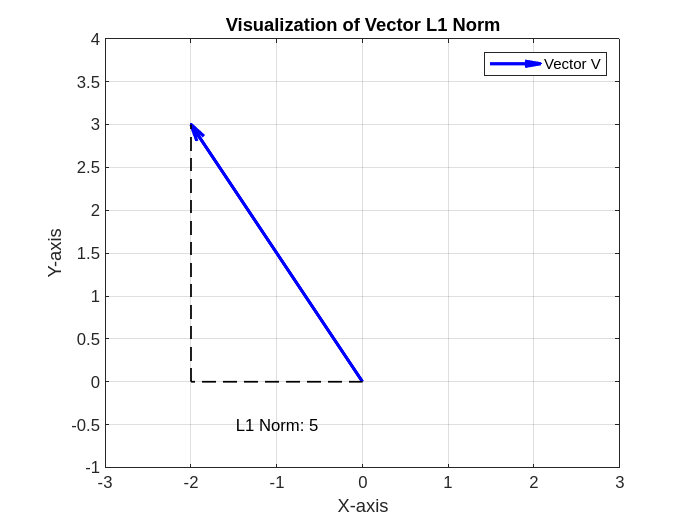

clc; clear; close all;

% Define vector
v = [-2, 3];

% Calculate L1 norm
l1_norm = norm(v, 1);

% Display vector from the origin
quiver(0, 0, v(1), v(2), 'b', LineWidth=2, AutoScale='off', DisplayName='Vector V');
hold on;

% Add lines representing movement along each axis to visualize Manhattan
% distance
plot([0, v(1)], [0, 0], '--k', LineWidth=1, HandleVisibility='off');
plot([v(1), v(1)], [0, v(2)], '--k', LineWidth=1, HandleVisibility='off');

% Display the value of L1 norm
text(v(1)/2 , -0.5, ['L1 Norm: ', num2str(l1_norm)], 'HorizontalAlignment', 'center');

% Set axes properties
axis equal;
xlim([-3, 3]);
ylim([-1, 4]);

% Show grid
grid on;

% Title for visualization of vector L1 norm
title('Visualization of Vector L1 Norm');

% Axes labels
xlabel('X-axis');
ylabel('Y-axis');

% Legend for vectors and movement along axes
legend("show");

### Code Exercise (02_08)

> L2 norm(Euclidean norm)

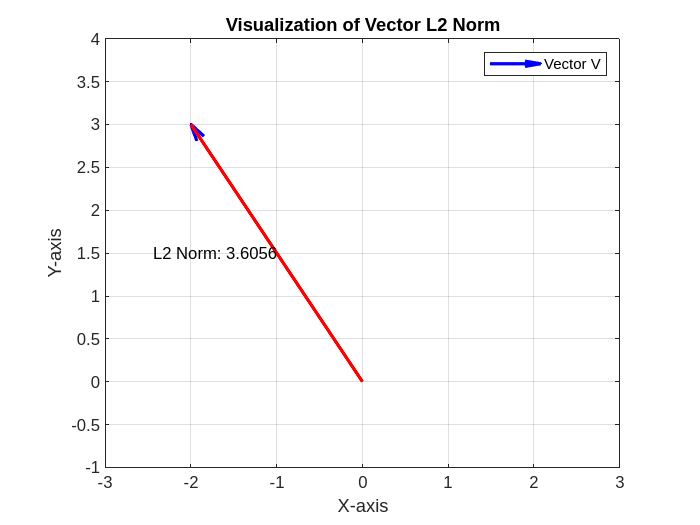

clear; close all; clc;

% Define vector
v = [-2, 3];

% Calculate L2 norm
l2_norm = norm(v, 2);

% Display vector from the origin
quiver(0, 0, v(1), v(2), 'b', LineWidth=2, AutoScale='off', DisplayName='Vector V');
% quiver(0, 0, v(1), v(2), 'b', LineWidth=2, AutoScale='off', HandleVisibility='off');

hold on;

% Add line representing the vector to illustrate its magnitude
plot ([0, v(1)], [0, v(2)], 'r', LineWidth=2, HandleVisibility='off');

% Display the value of L2 norm
text(v(1)/2, v(2)/2, ['L2 Norm: ', num2str(l2_norm)], 'HorizontalAlignment', 'right');

% Set axes properties
axis equal;
xlim([-3, 3]);
ylim([-1, 4]);

% Show grid
grid on;

% Title for visualization of vector L2 norm
title('Visualization of Vector L2 Norm');

% Axes labels
xlabel('X-axis');
ylabel('Y-axis');

% Legend for vectors
legend("show");

### Code Exercise (02_09)

> Vector norm & length

clc; clear; close all;

% Vector Norm
v = [-2, 3];

% Norm of vector
v_L1_norm = norm(v, 1);
v_L2_norm = norm(v, 2);

% Display norm of vector

disp(['Vector L1 norm: ', num2str(v_L1_norm)]);

Vector L1 norm: 5


disp(['Vector L2 norm: ', num2str(v_L2_norm)]);

Vector L2 norm: 3.6056


### Code Exercise (02_10)

> dot() function

clc; clear; close all;

% Dot product
v = [0, 1, 2];
u = [13, 21, 34];

s = 10;

% scala multiplcate dot product
dot_product = dot(v, u);
scala_multiplicated = dot(s*v, u);

% show the result
disp('Dot Product:');

Dot Product:


disp(dot_product);

    89



disp('Scalar multiplicated:');

Scalar multiplicated:


disp(scala_multiplicated);

   890



### Code Exercise (02_11)

> Distributive law of dot product.

% The dot product is distributive

% some random vectors
v = [0, 1, 2];
w = [3, 5, 8];
u = [13, 21, 34];

% two ways to compute
res1 = dot(v, w + u);
res2 = dot(v, w) + dot(v, u);

% show that they are equivalent
disp('res1:');

res1:


disp(res1);

   110



disp('res2:');

res2:


disp(res2);

   110



### Code Exercise (02_12)

> Operation crsoss product between two vectors, one along the column direction and the other along the row direction

close all; clear; clc;

% Two vectors
row_vector = [-1 0 0];
column_vector = [0; -2; 0];

% cross product
cross_product = cross(row_vector, column_vector);

% result
disp('Cross Product:');

Cross Product:


disp(cross_product);

     0     0     2



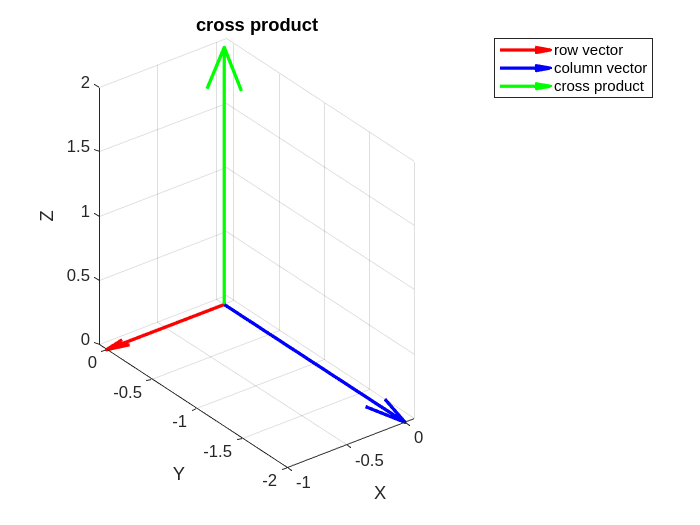


% visualization
figure;
quiver3(0, 0, 0, row_vector(1), row_vector(2), row_vector(3), 'r', LineWidth=2, AutoScale='off', MaxHeadSize=0.5, DisplayName='row vector');
hold on;

quiver3(0, 0, 0, column_vector(1), column_vector(2), column_vector(3), 'b', LineWidth=2, AutoScale='off', MaxHeadSize=0.5, DisplayName='column vector');
quiver3(0, 0, 0, cross_product(1), cross_product(2), cross_product(3), 'g', 'LineWidth', 2, AutoScale='off', MaxHeadSize=0.5, DisplayName='cross product');

legend("show");

xlabel('X');
ylabel('Y');
zlabel('Z');
title('cross product');
axis equal;
grid on;

### Code Exercise (02_13)

> Multiplication between two vectors or matrices

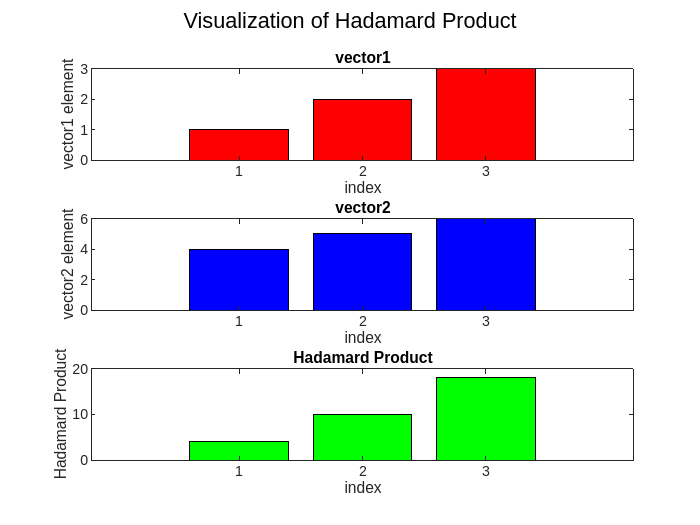

clc; clear; close all;

% two vectors
vector1 = [1 2 3];
vector2 = [4 5 6];

% Hadamard product - operator: .*
hadamard_product = vector1 .* vector2;

% plot
subplot(3, 1, 1);
bar(vector1, 'r');
xlabel('index');
ylabel('vector1 element');
title('vector1');

subplot(3, 1, 2);
bar(vector2, 'b');
xlabel('index');
ylabel('vector2 element');
title('vector2');

subplot(3, 1, 3);
bar(hadamard_product, 'g');
xlabel('index');
ylabel('Hadamard Product');
title('Hadamard Product');

sgtitle('Visualization of Hadamard Product');

### Vertical Component Generated from Target Vector

>  Page 62

clear; close all; clc;

t = [3 4 5];
r = [9 5 7];

B = dot(r', t)/dot(r',r);

disp('Proof vertical component');

Proof vertical component


disp(dot((t-r*B)', r));

  -3.5527e-15

